clear


global m nm kg sec J eV mass_e h_bar V_b k_1 k_2 n_e e_0 Epsi0 pi e nm1 mass
m = 1;
kg = 1;
sec = 1;
J = 1;
pi = 3.141592;
nm = 1E-9 *(m);
nm1 = (2.40) *(nm);
eV = 1.60218E-19 *(J);
e    = 1.602176487E-19;
mass = 0.067*9.10938e-31 *(kg);
mass_e = 0.067*9.10938e-31 *(kg);
h_bar = (6.62607E-34)/(2*pi) *(J*sec);
V_b = 97e-3*eV;
k_1 = 0.696e-3*eV/nm;
k_2 = -0.017034e-3*eV/nm^2;
n_e = 1e15*m^(-2);
e_0 = -3.4666e-3*eV;
Epsi0 = 8.854187817620e-12*12.9;
k_f = 2*pi*n_e;
k_f = sqrt(k_f);
R = (k_f);
dz = 0.25 *(nm); % Increments
zRange = 98.0 *(nm); %Z-Range of the graph
qWell_wide = 49.0 *(nm); %Size of the well
z = (-zRange/2:dz:zRange/2+dz); %Z-range to be graphed
K_B = 8.617*10^(-5); % Boltzmann Constant in eV/K
%E_F = 0.0016

### Energy Dispersion Relationship after Adding B Field

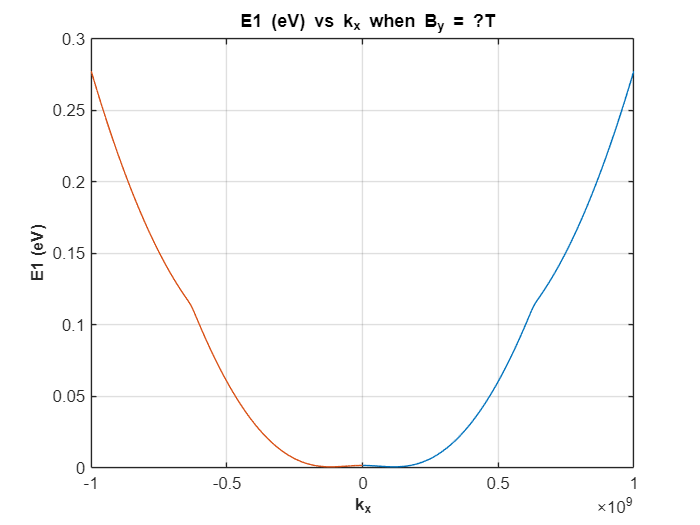

format long g
k_x = (0:0.001/nm :1/nm)';
load("E_0.mat")
load("V_2.mat")
load("V_H.mat")
B = [1,3,5,6.5,6.673,9,10,12,15,4.7,7,8,6.75,6.72,6.66,3.1]';
B2 = [0,0.1,1.5,3.1,3.6,6.673,10,8,9,15];
B_indx = 2;
B2_indx =6;
B_y = B2(B2_indx);%Set the magnitude of the in-plane magnetic field
omega = abs(e)*(B_y)/mass_e;%Calculate parameter-Omega
z_0 = (h_bar*k_x)/(mass_e*omega);%Calculate z0
Ex1 = zeros(1,1001);
Ex2= zeros(1,1001);
n = 1;
%Iterate through 
for n = 1:length(Ex1)
    E_n = ((mass_e)*(omega)^2)*(z-(z_0(n)*ones(1,length(z)))).^2/2;
    V_tot = V_2 + E_n;
    H0_3 = diag((h_bar^2/(mass_e*dz^2)) + V_tot);
    H1_3 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),1);
    H2_3 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),-1);
    H_3 = H0_3+H1_3+H2_3;
    [fn3,En3] = eig(H_3);
    ex1 = En3(1,1)/eV;
    ex2 = En3(2,2)/eV;
    Ex1(n) = ex1;
    Ex2(n) = ex2;
end

plot(k_x, Ex1, -k_x, Ex1)
grid on
title(' E1 (eV) vs k_x when B_y = ?T')
xlabel('k_x','fontweight','bold','fontsize',10)
ylabel('E1 (eV)','fontweight','bold','fontsize',10)

### Fermi Energy at B_y = ?T

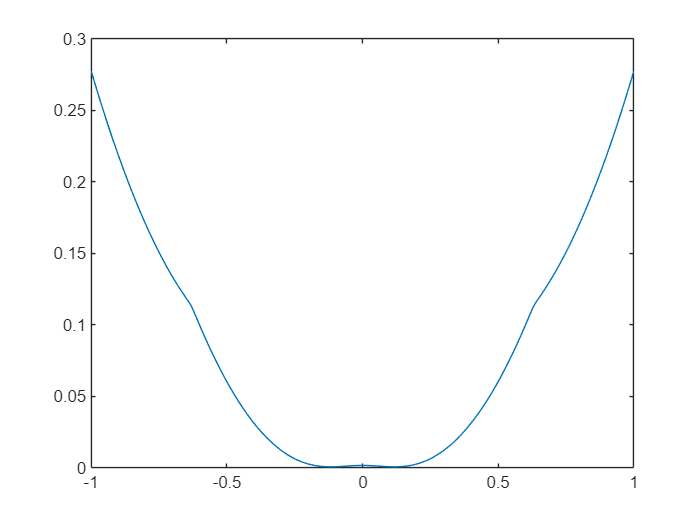

Ex0 = [flip(Ex1), Ex1]; %Put energy dispersion into an array
kx = linspace(-1/nm,1/nm,2002);
ky = linspace(-1/nm,1/nm,2002);
plot(kx*nm,Ex0)

[Ex,ky]=meshgrid(Ex0,ky);%Span them to the same size matrix
E_tot = Ex + (h_bar * ky).^2/(2*mass_e*eV);%Energy dispesion in 2D

% Could test when B = 0T
%[kx,ky]=meshgrid(kx,ky);                               
%E_tot = (h_bar * kx).^2/(2*mass_e*eV) + (h_bar * ky).^2/(2*mass_e*eV);


E_flat = sort(round(E_tot(:), 6,"significant"));%Sort the energy in ascending way
dk = 0.001/nm;%Iteration step
E_max = 0;%Initial value of Fermi energy



%Iterate through E_flat and calculate the Fermi Energy
for i = 1:length(E_flat)
    E_max_trial = E_flat(i); % Current trial Fermi energy
    n_states = 0;% Initialize the electron density counter
    for j = 1:length(kx)
        if E_max_trial > Ex0(j) % Check if E_F > E(k_x)
            % Add contribution to n_states
            n_states = n_states + (sqrt((2 * mass_e / h_bar^2)*(E_max_trial - (Ex0(j)))*eV)*dk)/(pi^2);
        end
    end
   if abs(n_states) > n_e && abs(n_states - n_e) <= 0.001 * n_e %Determination of Fermi Energy %0.001 n_e
        E_max = E_max_trial; % Save the Fermi energy
        disp('Condition met. Breaking the loop.');
        display(E_max);
        break; % Exit the loop
    end
end

Condition met. Breaking the loop.


E_max =                 0.00143238


n_states

n_states =       1.00001824504582e+15


E_min = min(E_flat);
E_fermi = E_max - min(E_flat)

E_fermi =                0.000956197


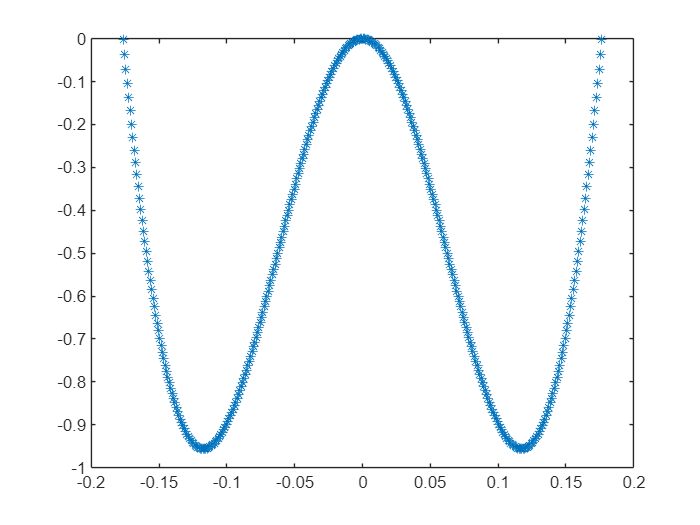

T_fermi = E_fermi/K_B;
abs(abs(n_states) - n_e);
Ex_indx = Ex0 <= E_max;  
Exless = (Ex0(Ex_indx) -E_max)'*10^3;
kxless = kx(Ex_indx)'*nm;
plot(kxless,Exless,'*')

### Verfiy if it's somehow critical B field

% dE_dx = diff(Exless) ./ diff(kxless);
% d2E_dx2 = diff(dE_dx) ./ diff(kxless(1:end-1));
%plot(kxless(1:end-2), d2E_dx2, 'o');
%xlabel('kx');
%ylabel('Second Derivative d^2E/dx^2');

### Energy Dispersion under Fermi Energy Zero Field

%grid on;
%xlabel('B_y (T)', 'FontSize', 12);
%ylabel('Fermi Energy (eV)', 'FontSize', 12);
%title('Fermi Energy vs B_y', 'FontSize',14);
%E0_indx = E_0 < 0;  
%Exless0 = E_0(E0_indx)'*10^3;
%kxless0 = -k_f:(k_f*2/153):k_f;
%kxless0 = kxless0'*nm;
%plot(kxless0,Exless0,'*')

### Effectuve Mass vs. Energy at B_y = ?T or at Fermi Energy

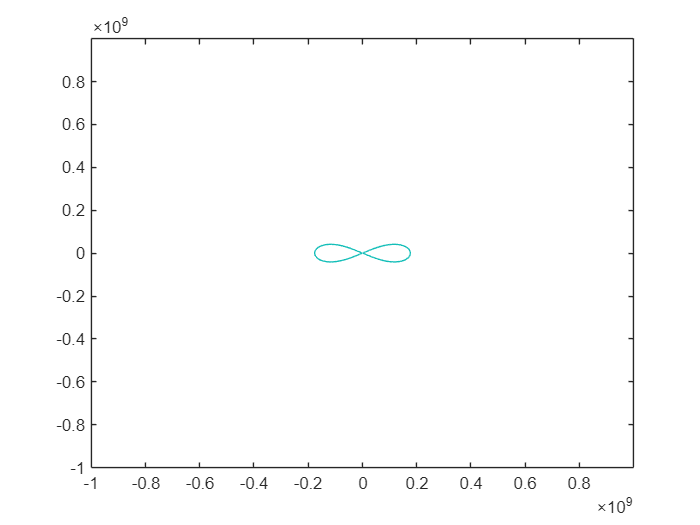

kx = linspace(-1/nm,1/nm,2002);
ky = linspace(-1/nm,1/nm,2002);
integral_value = 0;
[kx_grid, ky_grid] = meshgrid(kx, ky);
[Ex_kx, Ex_ky] = gradient(E_tot, kx(2) - kx(1), ky(2) - ky(1)); % Numerical derivatives
gradient_magnitude = sqrt((Ex_kx*eV).^2 + (Ex_ky*eV).^2); % |∇kE|
num_energy_points = 500; 
E_flat = unique(sort(round(E_tot(:), 4,"significant")));
E_range = linspace(min(E_flat(:)),20*E_max, num_energy_points); % Cause there are no points between min(E_flat) and E_fermi
MassE = zeros(size(E_range)); 
%%
E_range = E_max; % Condition for Effective Mass @ Fermi Energy, If you want to plot Effective Mass vs. Energy & LLs,please uncomment this line
Energy = E_range;


MassEFermi = 0;
for idx = 1:length(Energy)
    E_current = Energy(idx); %E_max;
    [C, ~] = contour(kx, ky, E_tot, [E_current, E_current]);

    Fermi1_kx = [];
    Fermi1_ky = [];
    col = 1;
    while col < size(C, 2)
        num_points = C(2, col);
        x_data = C(1, col+1:col+num_points);
        y_data = C(2, col+1:col+num_points);
        Fermi_kx = [Fermi1_kx; x_data'];
        Fermi_ky = [Fermi1_ky; y_data'];
        col = col + num_points + 1;
    end
%%
   if abs(Energy - E_max)*10^3 <= 1
       Fermi_kx = [-flip(Fermi_kx'),Fermi_kx'];
       Fermi_ky = [flip(Fermi_ky'),Fermi_ky'];
    end

    mass_integral = 0;
        for j = 1:(length(Fermi_kx))
            if j<(length(Fermi_kx))
            delta_k = sqrt((Fermi_kx(j+1) - Fermi_kx(j))^2 + (Fermi_ky(j+1) - Fermi_ky(j))^2);
            else
            delta_k = sqrt((Fermi_kx(j) - Fermi_kx(1))^2 + (Fermi_ky(j) - Fermi_ky(1))^2);  
            end
            [~, idx_kx] = min(abs(kx - Fermi_kx(j)));
            [~, idx_ky] = min(abs(ky - Fermi_ky(j)));
            grad_mag = gradient_magnitude(idx_ky, idx_kx);
            mass_integral = mass_integral + delta_k / abs(grad_mag);
        end
        MassE(idx) = (h_bar^2 / (2 * pi)) * mass_integral/mass_e;
        if all(Fermi_kx > 0)
            MassE(idx) = 2 * MassE(idx);
        end

end
Fermi1_kx = Fermi_kx*nm;
Fermi1_ky = Fermi_ky*nm;
hold off

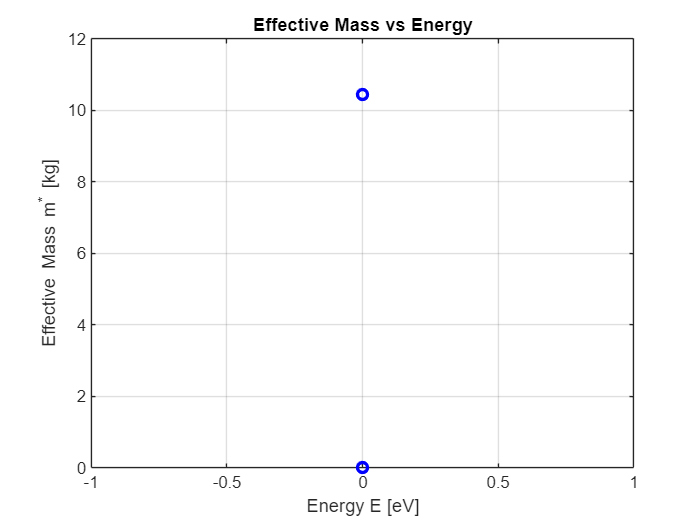

Energy1 = (Energy - E_max)'*10^3;
MassE = MassE';
EFMass(B_indx) = MassE(1);
EFMass;
figure;
plot(Energy1, MassE, 'b-o', 'LineWidth', 2);
xlabel('Energy E [eV]');
ylabel('Effective Mass m^* [kg]');
title('Effective Mass vs Energy');
grid on;

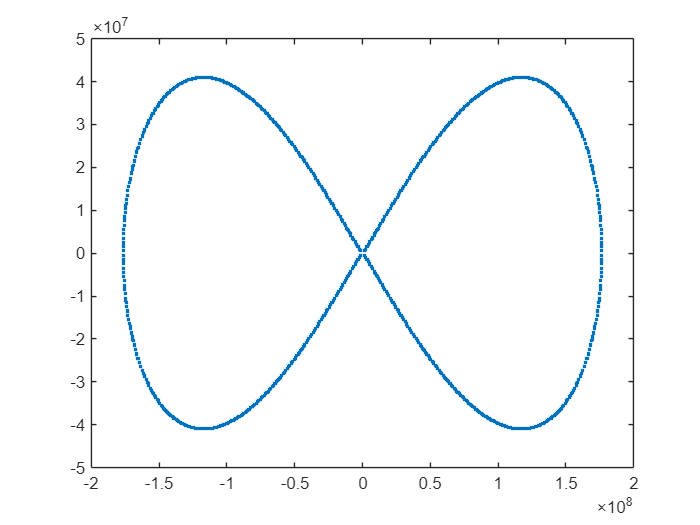

plot(Fermi_kx,Fermi_ky,'.')

## LLs Calculation

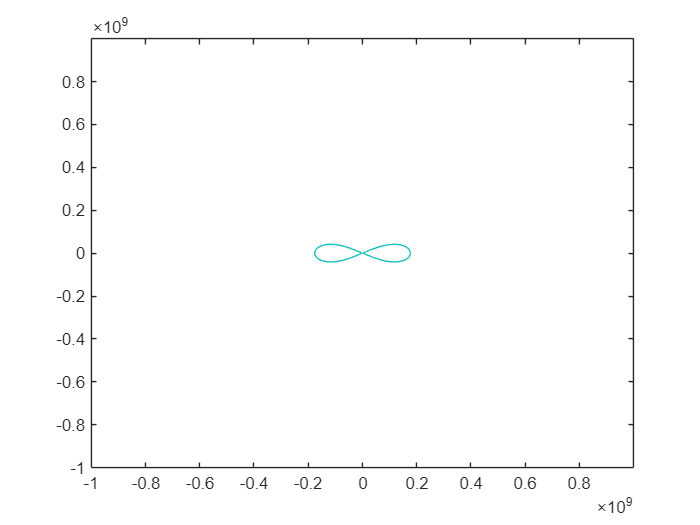

% N_energy = length(Energy);
% Landau_indices = zeros(1, N_energy); % Preallocate
% Area_list = NaN(1, N_energy);        % Preallocate area array
% B_per = 1.77;
% for idx = 1:N_energy
%     E_current = Energy(idx);
% 
%     % Extract constant-energy contour
%     [C, ~] = contour(kx, ky, E_tot, [E_current, E_current]);
% 
%     % Collect contour data points
%     Fermi_kx = [];
%     Fermi_ky = [];
%     col = 1;
%     while col < size(C, 2)
%         num_points = C(2, col);
%         x_data = C(1, col+1:col+num_points);
%         y_data = C(2, col+1:col+num_points);
%         Fermi_kx = [Fermi_kx; x_data'];
%         Fermi_ky = [Fermi_ky; y_data'];
%         col = col + num_points + 1;
%     end
% 
%     % Skip if contour is empty
%     if isempty(Fermi_kx) || isempty(Fermi_ky)
%         Landau_indices(idx) = NaN;
%         Area_list(idx) = NaN;
%         continue;
%     end
% 
%     % Sort the Fermi contour points
%     kx0 = Fermi_kx(:);
%     ky0 = Fermi_ky(:);
%     pts = [kx0, ky0];
%     N_pts = length(kx0);
%     path = zeros(N_pts,1);
%     used = false(N_pts,1);
%     path(1) = 1;
%     used(1) = true;
% 
%     for i = 2:N_pts
%         last = path(i-1);
%         dist = sum((pts - pts(last,:)).^2, 2);
%         dist(used) = inf;
%         [~, idx_min] = min(dist);
%         path(i) = idx_min;
%         used(idx_min) = true;
%     end
% 
%     kx_sorted = kx0(path);
%     ky_sorted = ky0(path);
% 
%     % Ensure contour is closed
%     if ~(kx_sorted(1) == kx_sorted(end) && ky_sorted(1) == ky_sorted(end))
%         kx_sorted(end+1) = kx_sorted(1);
%         ky_sorted(end+1) = ky_sorted(1);
%     end
% 
%     % Apply Green's theorem
%     delta_kx = diff(kx_sorted);
%     delta_ky = diff(ky_sorted);
% 
%     area_k = 0.5 * sum(kx_sorted(1:end-1) .* delta_ky - ky_sorted(1:end-1) .* delta_kx);
%     area_k = abs(area_k);
% 
% 
%     Area_list(idx) = area_k;
% 
%     % Compute quantized areas
%     Nmax = 30;
%     quantized_A = zeros(1, Nmax+1);
%     for N = 0:Nmax
%         quantized_A(N+1) = 2*pi*(N + 0.5)*e*B_per/h_bar;
%     end
% 
%     [area_diff, N_found] = min(abs(area_k - quantized_A));
%     relative_error = abs(area_diff / quantized_A(N_found));
% 
%     if relative_error <= 0.01
%         Landau_indices(idx) = N_found - 1;
%         else
%         Landau_indices(idx) = NaN;
%     end
% end

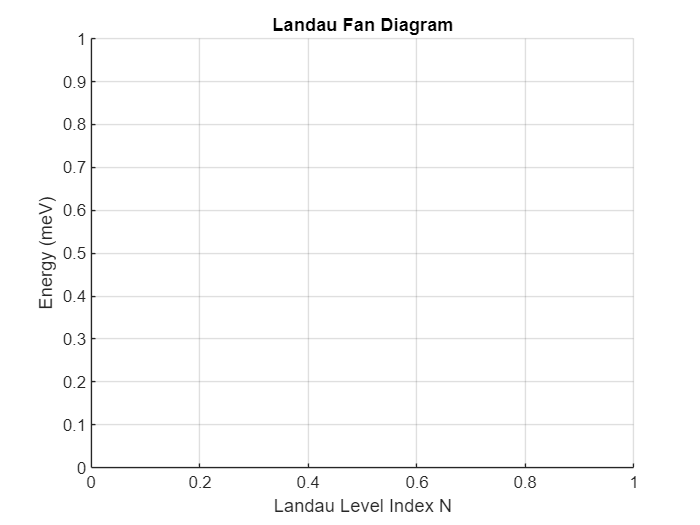

% unique_N = unique(Landau_indices(~isnan(Landau_indices))); 
% N_mean_list = [];
% E_mean_list = [];
% 
% for i = 1:length(unique_N)
%     N_val = unique_N(i);
% 
% 
%     idx_N = Landau_indices == N_val;
%     energies_N = Energy(idx_N);
% 
% 
%     if length(energies_N) < 1
%         continue
%     end
% 
%     N_mean_list(end+1) = N_val;
%     E_mean_list(end+1) = mean(energies_N);
% end
% 
% figure;
% plot(N_mean_list, E_mean_list*1000,  'o', 'LineWidth', 1.5);
% ylabel('Energy (meV)');
% xlabel('Landau Level Index N');
% title('Landau Fan Diagram');
% grid on;

% B_par = 1.77;
% A0 = pi*e*B_par/h_bar; %N = 0
% [area_diff_min, idx_closest] = min(abs(Area_list - A0));
% 
% E_closest = Energy(idx_closest);
% 
% fprintf('A0 = %.4e\n', A0);

A0 = 8.4481e+15


% fprintf('Closest area = %.4e (index %d)\n', Area_list(idx_closest), idx_closest);

Closest area = 1.9758e+16 (index 1)


% fprintf('Corresponding energy = %.6f eV\n', E_closest);

Corresponding energy = 0.001432 eV


### Factor \Psi(k_y) Out at B_y = 0T

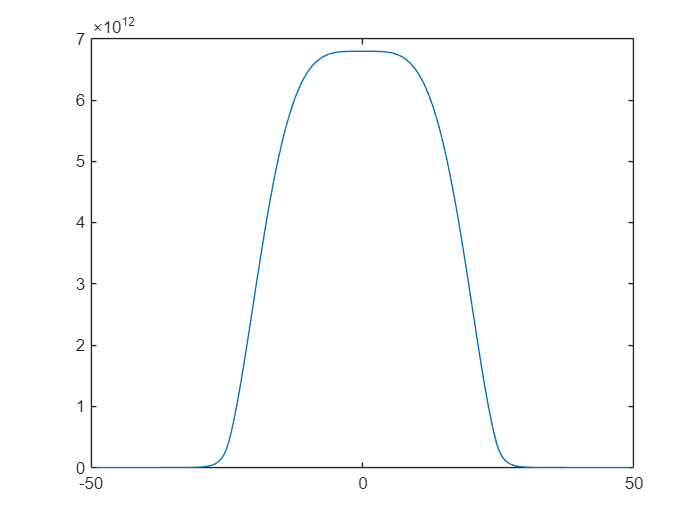

k_f = sqrt(2*pi*n_e);
theta0 = 0:pi/30:2*pi;
load("V_2.mat")
load("Psi_1_b0.mat")
nz0 = psi_1.^2;
nz0 = nz0*n_e;
plot(z'/nm,nz0);

trapz(nz0)

ans =            999999999999839


### **Plot Wavefunction for Different In-Plane Magnetic Field **

B0 = B_y;
Matrix = ones(394,201);
Matrix3 = ones(394,201);
Matrix4 = ones(1,201);
omega1 = abs(e)*(B0)/(mass_e);

% Split the Fermi contour into two lens-shaped regions based on k_x
Lens1_idx = Fermi_kx > 0;  % Left lens
Lens2_idx = Fermi_kx < 0;  % Right lens
lens1_kx = Fermi_kx(Lens1_idx);
lens1_ky = Fermi_ky(Lens1_idx);
lens2_kx = Fermi_kx(Lens2_idx);
lens2_ky = Fermi_ky(Lens2_idx);
% Extract points for each lens
% Sort Lens1_kx in ascending order and get the sorting indices
[Sorted_Lens1_kx, sortIdx1] = sort(lens1_kx);
% Reorder Lens1_ky using the same sorting indices
Sorted_Lens1_ky = lens1_ky(sortIdx1);
% Sort Lens1_kx in ascending order and get the sorting indices
[Sorted_Lens2_kx, sortIdx2] = sort(lens2_kx);
% Reorder Lens1_ky using the same sorting indices
Sorted_Lens2_ky = lens2_ky(sortIdx2);

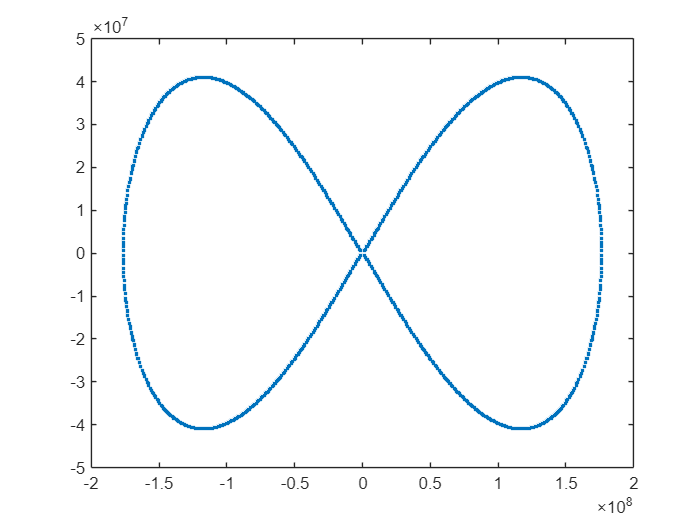

Fermi_kx = [Sorted_Lens2_kx;Sorted_Lens1_kx]; % I have to use the Fermi points at Fermi enrgy
Fermi_ky = [Sorted_Lens2_ky;Sorted_Lens1_ky]; 
plot(Fermi_kx, Fermi_ky,'.')

## Electrons Distribution

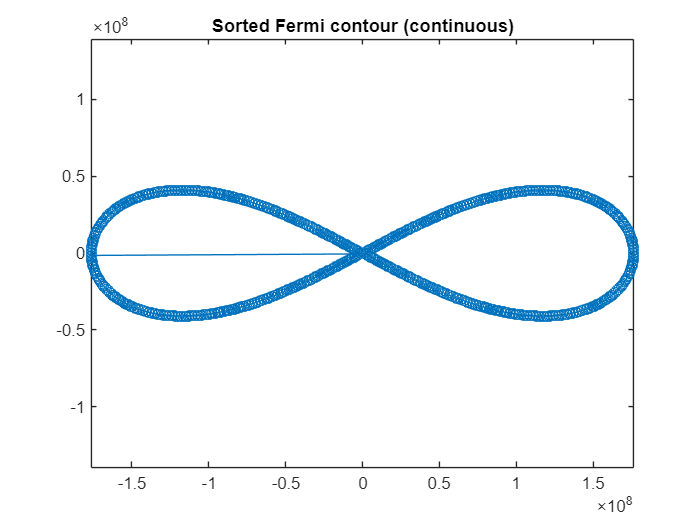

kx = Fermi_kx(:);
ky = Fermi_ky(:);

% Combine into one array
pts = [kx, ky];

% Initialize path
N = length(kx);
path = zeros(N,1);
used = false(N,1);

% Start from the first point
path(1) = 1;
used(1) = true;

for i = 2:N
    last = path(i-1);
    dist = sum((pts - pts(last,:)).^2, 2); % squared distance
    dist(used) = inf; % already used points are ignored
    [~, idx] = min(dist);
    path(i) = idx;
    used(idx) = true;
end

% Reorder the points
kx_sorted = kx(path);
ky_sorted = ky(path);

% Plot to check if path is continuous
figure;
plot(kx_sorted, ky_sorted, '-o');
axis equal;
title('Sorted Fermi contour (continuous)');


% Step 1: Ensure the contour is closed
if ~(kx_sorted(1) == kx_sorted(end) && ky_sorted(1) == ky_sorted(end))
    kx_sorted(end+1) = kx_sorted(1);
    ky_sorted(end+1) = ky_sorted(1);
end

% Step 2: Compute differences
delta_kx = diff(kx_sorted);
delta_ky = diff(ky_sorted);

% Step 3: Apply Green's theorem
area_k = 0.5 * sum(kx_sorted(1:end-1) .* delta_ky - ky_sorted(1:end-1) .* delta_kx);

% Ensure area is positive
area_k = abs(area_k);

fprintf('Area A(E_Fermi) = %.4e (in k-space units)\n', area_k);

Area A(E_Fermi) = 1.9676e+16 (in k-space units)



Nmax = 10;
quantized_A = zeros(1, Nmax+1);

for N = 0:Nmax
    quantized_A(N+1) = 2*pi*(N+0.5)*e*B_y/h_bar;
end

% Step 5: Display comparison
disp('Quantized target areas (in k-space units):');

Quantized target areas (in k-space units):


disp(quantized_A);

      3.18496760570091e+16      9.55490281710274e+16      1.59248380285046e+17      2.22947732399064e+17      2.86647084513082e+17        3.503464366271e+17      4.14045788741119e+17      4.77745140855137e+17      5.41444492969155e+17      6.05143845083173e+17      6.68843197197192e+17




% Step 6: Find closest matching N
[~, N_found] = min(abs(area_k - quantized_A));

fprintf('The contour corresponds approximately to Landau Level N = %d\n', N_found-1);

The contour corresponds approximately to Landau Level N = 0



for l = 1:length(Fermi_kx)
   z0 = h_bar*Fermi_kx(l)/(mass_e*omega1);%
   Matrix4(:,l) = z0;
end
for s = 1:length(Fermi_kx)
   E_m = (mass_e)*(omega1)^2 *(z-(Matrix4(s)*ones(1,length(z)))).^2*0.5;%
   V_tot1 = V_H+ E_m;
   Matrix3(:,s) = V_tot1;
    H0_1 = diag((h_bar^2/(mass_e*dz^2)) + V_tot1);%MassEFermi*
    H1_1 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),1);%MassEFermi*
    H2_1 = diag(ones(1,length(z)-1)*(-h_bar^2/(2*mass_e*dz^2)),-1);%MassEFermi*
    H_1 = H0_1+H1_1+H2_1;
    [fn,En] = eig(H_1);

    %Finding Wavefunction of new E1
    [d,ind] = sort(diag(En));
    psi_b = fn(:,ind);
    psi_1_b = psi_b(:,1);
    Matrix(:,s) = psi_1_b;
    V_tot1 = [];
end 

positive_values = Fermi_kx(Fermi_kx >= 0); 
[min_positive, min_idx] = min(positive_values); 
index1 = find(Fermi_kx == min_positive, 1);
index2 = length(Fermi_kx);

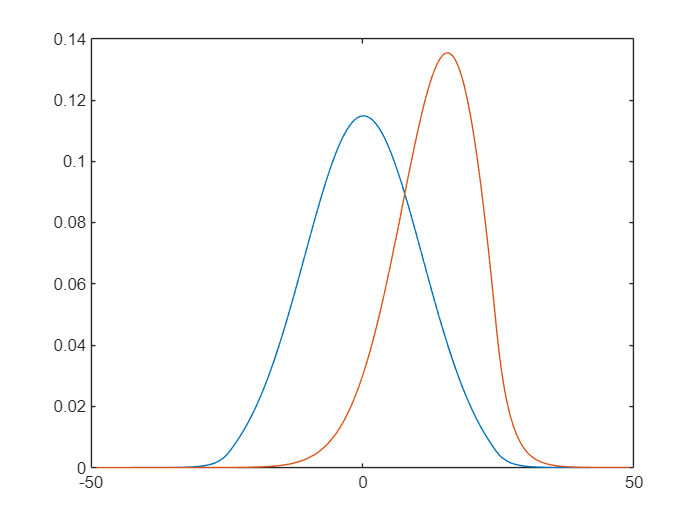

Minwave = abs(Matrix(:,index1));
Maxwave = abs(Matrix(:,index2));
plot(z/nm,abs(Matrix(:,index1)))
hold on
plot(z/nm,abs(Matrix(:,index2)))
hold off

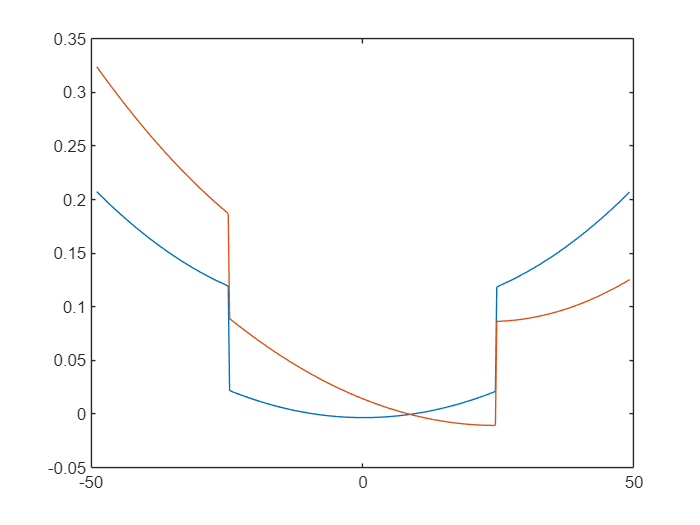

Minwell = Matrix3(:,index1)/eV;
Maxwell = Matrix3(:,index2)/eV;
plot(z/nm,Minwell)
hold on
plot(z/nm, Maxwell)
hold off

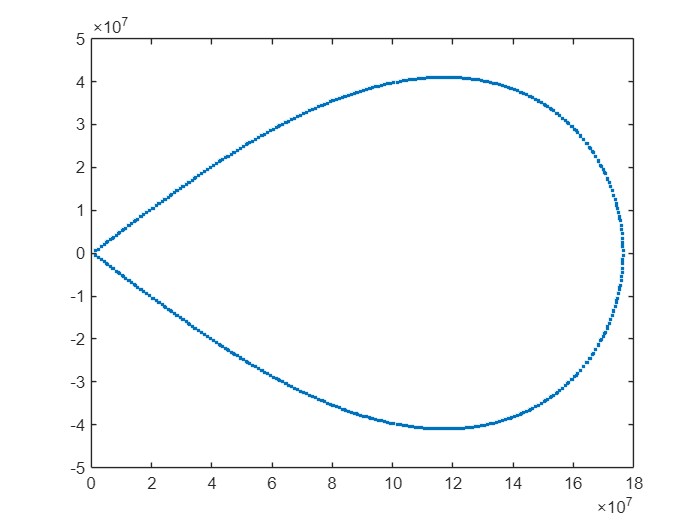

plot(Sorted_Lens1_kx,Sorted_Lens1_ky,'.')

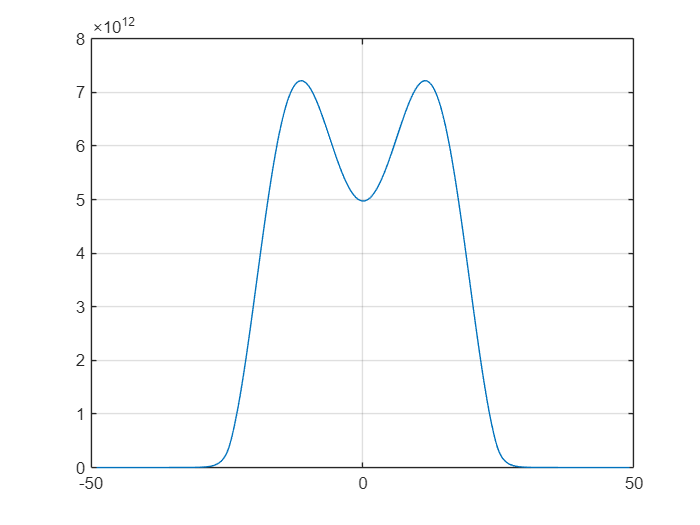

% Split the matrix into two parts
Matrix1 = Matrix(:, index1:index2);     % First half

% Initialize n(z)
n_z1 = zeros(394,1);
% Loop through both lenses
for o = 1:length(Sorted_Lens1_kx)
    if o < length(Sorted_Lens1_kx)
        dkx = Sorted_Lens1_kx(o+1) - Sorted_Lens1_kx(o);
    else
        dkx = abs(Sorted_Lens1_kx(1) - Sorted_Lens1_kx(o));
    end
      n_z1 = n_z1 + abs(Matrix1(:,o)).^2 .* dkx* 2*(abs(Sorted_Lens1_ky(o)));
end

n_z1 = flip(n_z1) + n_z1;
n_z = (1/(2*pi)^2*(2*n_z1));
plot(z/nm,n_z)
grid on

trapz(n_z/n_e)

ans =            1.0157874749432


V_tot1 = V_tot1';
Fermi1_kx = Fermi1_kx';
Fermi1_ky = Fermi1_ky';

### Save Our Data

Minwell = Minwell*10^3;
Maxwell = Maxwell*10^3;
load("V_H.mat")
%Exless1_5 = Exless;
%kxless1_5= kxless;
%Fermi1_kx1_5= Fermi1_kx;
%Fermi1_ky1_5 = Fermi1_ky;
%Minwave1_5 = Minwave;
%Maxwave1_5 = Maxwave;
%Minwell1_5 = Minwell;
%Maxwell1_5 = Maxwell;
%save('C:\Users\Mengyao Zhang\Desktop\UROP_mat_data\data1_5.mat', 'Exless1_5','kxless1_5', 'Fermi1_ky1_5','Fermi1_kx1_5','Minwave1_5','Maxwave1_5','Minwell1_5','Maxwell1_5')
V_H = V_H'*10^3/eV';

### Calculate Confined Potential Energy

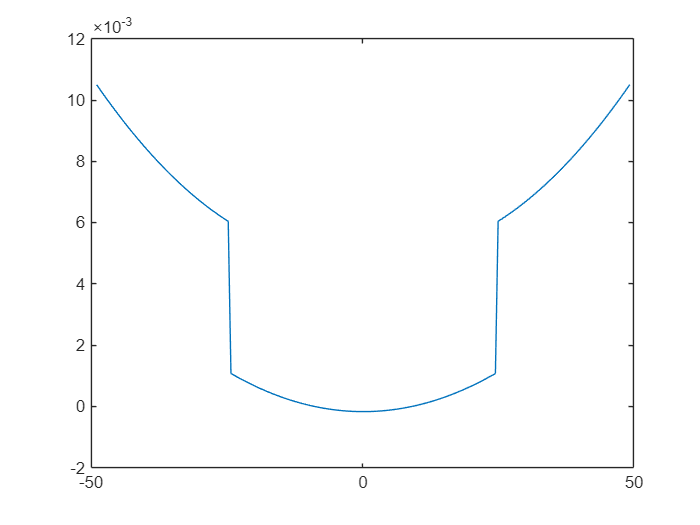

Vz0 = zeros(394,1);
area = 0;
% Loop through both lenses
for p = 1:length(Sorted_Lens1_kx)
    if p < length(Sorted_Lens1_kx)
        dkx = Sorted_Lens1_kx(p+1) - Sorted_Lens1_kx(p);
    else
        dkx = abs(Sorted_Lens1_kx(1) - Sorted_Lens1_kx(p));
    end
      Vz0 = Vz0 + Matrix3(:,o) .* dkx* 2*(abs(Sorted_Lens1_ky(p)));
      area = area + dkx* 2*(abs(Sorted_Lens1_ky(p)));
end


Vz = flip(Vz0) + Vz0;
Vz = (1/(2*pi)^2*(2*Vz/eV))/(2*area);
plot(z/nm,Vz)

### Test the Consistency

% denstate = MassE * mass_e/(pi*h_bar^2);
% Energy_indx = Energy<0
% Energy1 = (Energy(Energy_indx)/10^3+E_max)*eV
% dEnergy1 = mean(diff(Energy1))
% 
% n = 0
% for h = 1: length(Energy1)
%    n = n + dEnergy1*abs(denstate(h));
% end
% n/10^15

## Calculate Landau Level(Wrong)

% m_eff = mass_e*MassE(1);  
% 
% n_max = 5; % Maximum number of Landau levels to check
% E_fermi1 = 1000*E_fermi
% 
% omega_c = e * B_y / m_eff; 
% E_n = h_bar * omega_c * ((0:n_max) + 0.5); % Landau level energy (J)
% E_n_meV = E_n / e * 1000; % Convert to meV
% 
% % **Find the highest occupied Landau level (n_F)**
% n_F = find(E_n_meV <= E_fermi1, 1, 'last');
% 
% % **Display results**
% fprintf('Given Fermi energy: %.2f meV\n', E_n_meV);
% fprintf('Cyclotron frequency: %.2e rad/s\n', omega_c);
% fprintf('Highest occupied Landau level: n_F = %d\n', n_F);
% fprintf('Landau level energy E_n_F: %.2f meV\n', E_n_meV(n_F+1));
% 
% % **Plot Landau Levels**
% figure;
% stem(0:n_max, E_n_meV, 'b', 'LineWidth', 2);
% hold on;
% yline(E_fermi1, 'r--', 'LineWidth', 2, 'Label', 'Fermi Energy');
% xlabel('Landau Level Index n');
% ylabel('Energy (meV)');
% title(['Landau Levels and Fermi Energy (B = ' num2str(B_y) 'T)'],'FontSize', 6);
% grid on;
